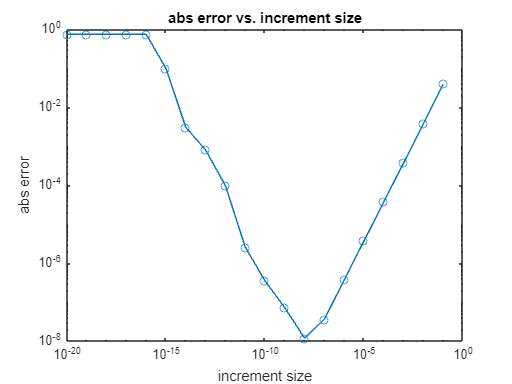

%%%         Question 6

func = @(x) exp(-x^2); %% cast f(x) into func

x_val = 1; %% the x value of the point we're estimating

%% make 2 arrays to hold the increment sizes & the asociated guesses
h_vals = zeros(20, 1);  approx_vals = zeros(20, 1);

for n_val = 1:20 %% loop from 1 to 20
    h_val = 10^(-n_val); %% find increment size
    approx_val = (func(x_val + h_val) - func(x_val)) / h_val; h_vals(n_val) = h_val; %% then we implement the fwd difference formula
    approx_vals(n_val) = approx_val; %% save the variables
end

%% plot:
loglog(h_vals, abs(approx_vals - (-2 * exp(-1))), '-o');
xlabel('increment size'); ylabel('abs error'); title('abs error vs. increment size');


%%%         Question 7

%%%     Question 1

func_integrate = @(x) exp(2*x) .* sin(3*x); %% cast f(x) into func
lower_lim = 0;        upper_lim = 2; %% declare the bounds of intergation
n_vals = [8, 16, 32, 64]; %% define the sub intervals

integral_approxs = zeros(size(n_vals)); %% make an array to hold the subintervals

for idx = 1:length(n_vals) %% loop through all intervals
    h_val = (upper_limit - lower_limit) / n_vals(idx); %% find the width of intervals
    x_nodes = linspace(lower_limit, upper_limit, n_vals(idx) + 1);%% find the ends of intervals
    y_vals = func_integrate(x_nodes); %% compute the function at the nodes
    integral_approxs(idx) = h_val * (sum(y_vals) - 0.5 * (y_vals(1) + y_vals(end))); %% calculate composite trapezoid funciton
end

%% print
disp('approximations of our integral using the composite trapezoidal rule');    disp(integral_approxs);

approximations of our integral using the composite trapezoidal rule
  -13.5760  -14.0532  -14.1737  -14.2039




%%%     Question 3

func_integrate = @(x) exp(2*x) .* sin(3*x);  %% cast f(x) into func
lower_lim = 0;        upper_lim = 2; %% declare the bounds of intergation
n_vals = [8, 16, 32, 64]; %% define the sub intervals
integral_approxs = zeros(size(n_vals)); %% make an array to hold the subintervals

for idx = 1:length(n_vals) %% loop through all intervals
    h_val = (upper_limit - lower_limit) / n_vals(idx); %% find the width of intervals
    x_nodes = linspace(lower_limit, upper_limit, n_vals(idx) + 1); %% find the ends of intervals
    y_vals = func_integrate(x_nodes); %% compute the function at the nodes
    integral_approxs(idx) = h_val/3 * (y_vals(1) + 4*sum(y_vals(2:2:end-1)) + 2*sum(y_vals(3:2:end-2)) + y_vals(end));%%calculate the simpsons value
end

%%print
disp('pproximations of integral using composite simpsons');    disp(integral_approxs);

pproximations of integral using composite simpsons
  -14.1833  -14.2123  -14.2139  -14.2140




%%%     Question 5

func_integrate = @(x) exp(2*x) .* sin(3*x);  %% cast f(x) into func
lower_lim = 0;        upper_lim = 2; %% declare the bounds of intergation
n_vals = [8, 16, 32, 64]; %% define the sub intervals
integral_approxs = zeros(size(n_vals)); %% make an array to hold the subintervals

% Loop over different values of n
for idx = 1:length(n_vals)
    h_val = (upper_limit - lower_limit) / (n_vals(idx) + 2); %% find the width of intervals
    x_midpoints = linspace(lower_limit + h_val, upper_limit - h_val, n_vals(idx)); %% find the middle points of the sub intervals
    y_vals = func_integrate(x_midpoints); %% compute the function at the midpoints
    integral_approxs(idx) = h_val * sum(y_vals); %%calculate the midpoint formula value
end

%% print
disp('Approximations of the integral using composite midpoint rule:');    disp(integral_approxs);

Approximations of the integral using composite midpoint rule:
  -11.0820  -12.4914  -13.3186  -13.7592

